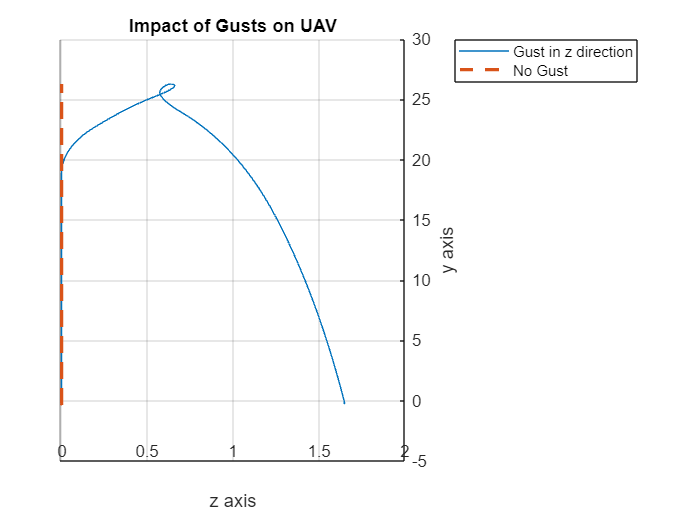

%Plot position of UAV 
%Change variable names based on variable names when importing for different
%cases
plot3(PositionX2,PositionY2,PositionZ2);
hold on;
plot3(PositionX3,PositionY3,PositionZ3,'LineStyle','--','LineWidth',2);

title('Impact of Gusts on UAV');
ylabel('y axis');
xlabel('x axis');
zlabel('z axis');
legend('Gust in z direction','No Gust')
view([90 180])
camup([0 1 0])

grid on;
hold off;

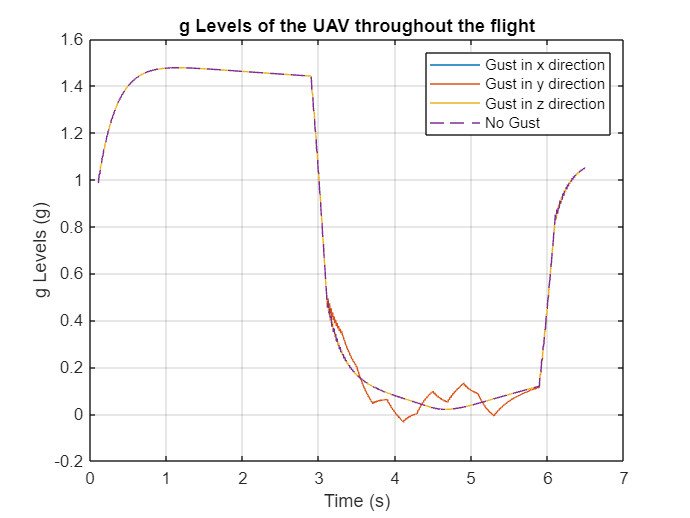


plot3(PositionX2,PositionY2,PositionZ2);
hold on;
plot3(PositionX3,PositionY3,PositionZ3,'LineStyle','--','LineWidth',2);

title('Impact of Gusts on UAV');
ylabel('y axis');
xlabel('x axis');
zlabel('z axis');
legend('Gust in z direction','No Gust')
view([90 180])
camup([0 1 0])

grid on;
hold off;


%Calculate Acceleration at each time step for each flight
g = 9.81;
Timestep = 0.01;
AccY = zeros(length(VelocityY),1);
for j = 1:length(VelocityY)
    if j == 1
        AccY(j,1) = NaN;
    else
        AccY(j,1) = (VelocityY(j,1)- VelocityY(j-1,1))/Timestep;
    end
end

AccY1 = zeros(length(VelocityY1),1);
for j = 1:length(VelocityY1)
    if j == 1
        AccY1(j,1) = NaN;
    else
        AccY1(j,1) = (VelocityY1(j,1)- VelocityY1(j-1,1))/Timestep;
    end
end

AccY2 = zeros(length(VelocityY2),1);
for j = 1:length(VelocityY2)
    if j == 1
        AccY2(j,1) = NaN;
    else
        AccY2(j,1) = (VelocityY2(j,1)- VelocityY2(j-1,1))/Timestep;
    end
end

AccY3 = zeros(length(VelocityY3),1);
for j = 1:length(VelocityY3)
    if j == 1
        AccY3(j,1) = NaN;
    else
        AccY3(j,1) = (VelocityY3(j,1)- VelocityY3(j-1,1))/Timestep;
    end
end

%Moving average of acceleration for each flight
data1 = AccY;
windowSize = 20;
n = length(data1);
movingAverage_1 = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_1(i) = mean(data1(startIdx:endIdx));
end

windowSize = 20;
n = length(Time);
movingAverage_Time = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_Time(i) = mean(Time(startIdx:endIdx));
end

data1 = AccY1;
windowSize = 20;
n = length(data1);
movingAverage_2 = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_2(i) = mean(data1(startIdx:endIdx));
end

data1 = AccY2;
windowSize = 20;
n = length(data1);
movingAverage_3 = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_3(i) = mean(data1(startIdx:endIdx));
end

data1 = AccY3;
windowSize = 20;
n = length(data1);
movingAverage_4 = zeros(1, n);

for i = 1:n
    % Define the window range
    startIdx = max(1, i - floor(windowSize / 2));
    endIdx = min(n, i + floor(windowSize / 2));

    % Compute the average
    movingAverage_4(i) = mean(data1(startIdx:endIdx));
end

%Plot the acceleration (g) vs. time for each flight
plot(movingAverage_Time(:,1:650),(movingAverage_1(:,1:650) + g)/(g));
hold on;
plot(movingAverage_Time(:,1:650),(movingAverage_2(:,1:650) + g)/(g));
plot(movingAverage_Time(:,1:650),(movingAverage_3(:,1:650) + g)/(g));
plot(movingAverage_Time(:,1:650),(movingAverage_4(:,1:650) + g)/(g),'LineStyle','--');
xlabel('Time (s)');
ylabel('g Levels (g)');
title('g Levels of the UAV throughout the flight')
legend('Gust in x direction', 'Gust in y direction', 'Gust in z direction','No Gust','Location','northeast')
grid on;
hold off;